## Określenie liczebności próby losowej

- Założenie:  populacja ma rozkład normalny

## 
$$n_{\min } =t_{\frac{\alpha }{2}}^2 \frac{{\hat{s} }^2 }{d^2 }$$


gdzie:

d - zakładana dokładność estymacji przedziałowej (połowa długości przedziału ufności),

${\hat{s} }^2$ - wariancja *próby wstępnej *liczącej $n_0$ elementów,

$t_{\frac{\alpha }{2}}$ - wartość zmiennej losowej o rozkładzie t-Studenta pola o mierze $\frac{\alpha }{2}$ (z prawej strony) - wartość krytyczna.

Przykład

clear all 
close all

format short

figure(1)
hold on
grid on
t = -5:0.1:5;
k=17

k = 17

yt = tpdf(t,k);

plot(t,yt,'LineWidth',2)

p=0.95 %poziom ufności 95%

p = 0.9500

alpha=1-p

alpha = 0.0500

t1=tinv(p+alpha/2,k)

t1 = 2.1098

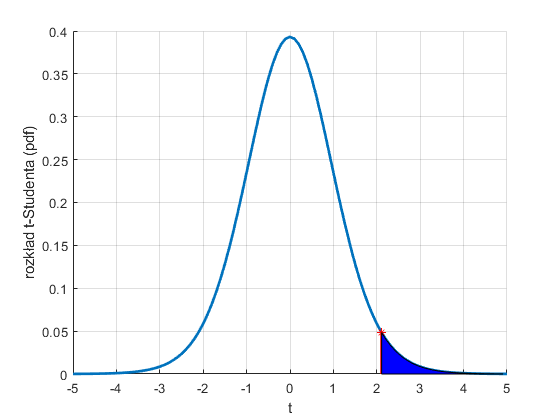


plot(t1,tpdf(t1,k),'r*')

a = [t1 t1];
b = [0 tpdf(t1,k)];
line(a,b,'Color','red','LineStyle','-','LineWidth',2)

t2 = t1:0.1:max(t);
y2 = tpdf(t2,k);
area(t2,y2,'FaceColor','b');
xlabel('t');
ylabel('rozkład t-Studenta (pdf)')



cenypaliwa=[
5.56
5.62
5.62
5.85
5.81
5.42
5.41
5.43
5.51
5.58
5.54
5.56
5.44
5.65
5.49
5.46
5.40
5.54]

cenypaliwa =     5.5600
    5.6200
    5.6200
    5.8500
    5.8100
    5.4200
    5.4100
    5.4300
    5.5100
    5.5800



p=0.95 %poziom ufnosci 95%

p = 0.9500

alpha=1-p

alpha = 0.0500


n=size(cenypaliwa,1) %liczebność

n = 18

k=n-1 %k=18-1 =17 liczba stopni swobody

k = 17


pLo = alpha/2;
pUp = 1 - alpha/2;

Zastosowanie funkcji [tinv()](https://www.mathworks.com/help/releases/R2020a/stats/tinv.html) (*Student's t inverse cumulative distribution function*) - odwrotność dystrybuanty dla rozkładu t-Studenta

crit = tinv([pLo pUp], k)

crit =    -2.1098    2.1098


t_alpha_2=crit(1,2) % wartość zmiennej losowej t "z prawej strony" odcinająca pole alpha/2

t_alpha_2 = 2.1098

odchylenie standardowe próby

s=std(cenypaliwa)

s = 0.1278

[wariancja ](https://pl.wikipedia.org/wiki/Wariancja)próby

s2=s^2

s2 = 0.0163

Chcemy aby błąd nie przekraczał d= 5 gr/l

d=0.05 % błąd zł/l zakładana dokładność estymacji 

d = 0.0500


nmin=t_alpha_2^2*s2/(d^2)

nmin = 29.0639

ceil(nmin-n)

ans = 12

Próba powinna liczyć 30 stacji benzynowych - a mieliśmy do dyspozycji n=18. Należy dolosować (losowo wybrać) dane 12 stacji.

Jeśli chcemy aby błąd nie przekraczał d= 1 gr/l

d=0.01 % błąd zł/l zakładana dokładność estymacji 

d = 0.0100


nmin=t_alpha_2^2*s2/(d^2)

nmin = 726.5983


ceil(nmin-n)

ans = 709

Próba powinna liczyć 727 stacji benzynowych - a mieliśmy do dyspozycji n=18. Należy dolosować (losowo wybrać) dane 709 stacji.

- **Gdy rozkład statystyczny populacji jest nieznany**

## 
$$n_{\min } =z_{\frac{\alpha }{2}}^2 \frac{{\hat{s} }^2 }{d^2 }$$


gdzie:

d - zakładana dokładność estymacji przedziałowej (połowa długości przedziału ufności),

${\hat{s} }^2$ - wariancja *próby wstępnej *liczącej $n_0$ $\left(n_0 \ge 30\right)$elementów,

$z_{\frac{\alpha }{2}}$ - wartość zmiennej losowej o rozkładzie **normalnym standaryzowanym** pola o mierze $\frac{\alpha }{2}$ ("ogon" z prawej strony wykresu gęstości prawdopodobieństwa).

figure(2)
hold on
grid on
z = -5:0.1:5;
ynorm = normpdf(z);
plot(z,ynorm,'LineWidth',2)

p=0.90 %poziom ufności 90%

p = 0.9000

alpha=1-p

alpha = 0.1000

z1=norminv(p+alpha/2)

z1 = 1.6449

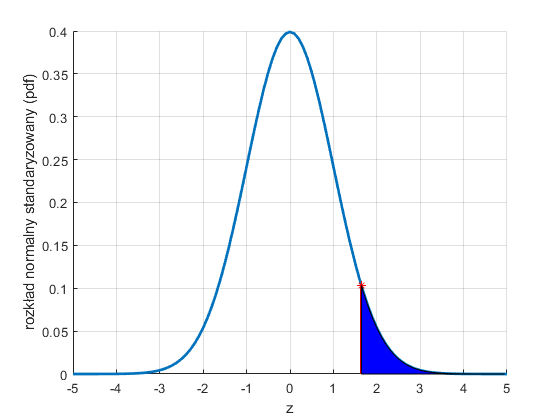


plot(z1,normpdf(z1),'r*')

a = [z1 z1];
b = [0 normpdf(z1)];
line(a,b,'Color','red','LineStyle','-','LineWidth',2)

z2 = z1:0.1:max(z);
y2 = normpdf(z2);
area(z2,y2,'FaceColor','b');
xlabel('z');
ylabel('rozkład normalny standaryzowany (pdf)')

Zadanie

n0=50 %klientów n0>=30 (pilotażowa duża liczba)

n0 = 50

s=2.3 %minuty - odchylenie standardowe próby

s = 2.3000

p=0.95 %poziom ufności 90%`

p = 0.9000

d=0.5 %dokładność do 0,5 minuty

d = 0.5000

Pytanie - czy liczebność wylosowanej "pilotażowej" próby jest wystarczająca?

alpha=1-p

alpha = 0.1000

pLo = alpha/2;
pUp = 1 - pLo;

Zastosowanie funkcji: odwrotność dystrybuanty rozkładu normalnego (funkcja [norminv](https://www.mathworks.com/help/releases/R2020a/stats/norminv.html)):

z_alpha_2=norminv(pUp)

z_alpha_2 = 1.6449

Minimalna liczebność póby obliczona jako:

nmin=z_alpha_2^2 *s^2/d^2

nmin = 57.2493

zaokrąglamy "w górę"

ceil(nmin)

ans = 58

Wylosowana wstępnie póba 50 klientów jest niewystarczająca. Należałoby "dolosować" 8 osób w celu zapewnienia oszacowania z wymaganą dokładnością i przy założonym poziomie ufności.

Gdy zmienimy parametry zadania:

p=0.9 %poziom ufności 90%`

p = 0.9000

d=0.1 %dokładność do 0,1 minuty

d = 0.1000


alpha=1-p

alpha = 0.1000

pLo = alpha/2;
pUp = 1 - pLo;
z_alpha_2=norminv(pUp)

z_alpha_2 = 1.6449


nmin=z_alpha_2^2 *s^2/d^2

nmin = 1.4312e+03

ceil(nmin)-n0

ans = 1382

Wylosowana wstępnie póba 50 klientów jest niewystarczająca. Należałoby "dolosować" 1382 osób w celu zapewnienia oszacowania z wymaganą dokładnością (d=0,1 minuty)i przy założonym poziomie ufności (90%).

Zastosowanie "ogólnej" funkcji odwrotności dystrybuanty [icdf](https://www.mathworks.com/help/releases/R2020a/stats/prob.normaldistribution.icdf.html) (*Inverse cumulative distribution function*). Należy wskazać dla jakiego rozkładu statystycznego są rozważania (funkcja [makedist](https://www.mathworks.com/help/releases/R2020a/stats/makedist.html)). 

n0=50

n0 = 50


p=0.9 %poziom ufności 90%`

p = 0.9000

d=0.1 %dokładność do 0,1 minuty

d = 0.1000


alpha=1-p

alpha = 0.1000

pLo = alpha/2;
pUp = 1 - pLo;

mu = 0;
sigma = 1;
pd = makedist('Normal','mu',mu,'sigma',sigma);
z_alpha_2= icdf(pd,pUp)

z_alpha_2 = 1.6449


nmin=z_alpha_2^2 *s^2/d^2

nmin = 1.4312e+03


ceil(nmin)-n0

ans = 1382

## Określenie liczebności próby losowej przy szacowaniu wskaźnika struktury populacji

## 
$$n_{\min } =z_{\frac{\alpha }{2}}^2 \frac{w\left(1-w\right)}{d^2 }$$


gdzie:

d - zakładana dokładność estymacji przedziałowej (połowa długości przedziału ufności),

w- wskaźnik struktury proby wyznaczony na podstawie próby pilotażowej lub przewidywany rząd wielkości wskaźnika struktury populacji

$z_{\frac{\alpha }{2}}$ - wartość zmiennej losowej o rozkładzie normalnym standaryzowanym pola o mierze $\frac{\alpha }{2}$ (z prawej strony).

Przykład

n=100

n = 100

Odsetek klientek gotowych kupić nowy produkt

w=26/n

w = 0.2600

Dokładność oszacowania 4%:

d=0.04

d = 0.0400

Współczynnik (poziom) ufności:

p=0.95

p = 0.9500

alpha=1-p

alpha = 0.0500

pLo = alpha/2;
pUp = 1 - pLo;

Obliczenia z zastosowaniem funkcji **norminv**

z_alpha_2=norminv(pUp)

z_alpha_2 = 1.9600

Minimalna liczebność próby

nmin=z_alpha_2^2 *w*(1-w)/d^2

nmin = 461.9354

zaokrąglamy "w górę"

ceil(nmin)

ans = 462

Z użyciem funkcji **icdf**

p=0.95

p = 0.9500

alpha=1-p

alpha = 0.0500

pLo = alpha/2;
pUp = 1 - pLo;

pd = makedist('Normal','mu',mu,'sigma',sigma);
z_alpha_2= icdf(pd,pUp)

z_alpha_2 = 1.9600


nmin=z_alpha_2^2 *w*(1-w)/d^2

nmin = 461.9354

ceil(nmin)

ans = 462

Gdy zwięszymy dokładność *d* do 2%:

d=0.02

d = 0.0200

nmin=z_alpha_2^2 *w*(1-w)/d^2

nmin = 1.8477e+03

ceil(nmin)

ans = 1848

## Określenie liczebności próby losowej przy szacowaniu wskaźnika struktury populacji gdy nie mamy żadych informacji o tym wskaźniku

w=0:0.01:1

w =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900



y=@(w) w.*(1-w)

y = function_handle with value:
    @(w)w.*(1-w)


xmax = 0.5000

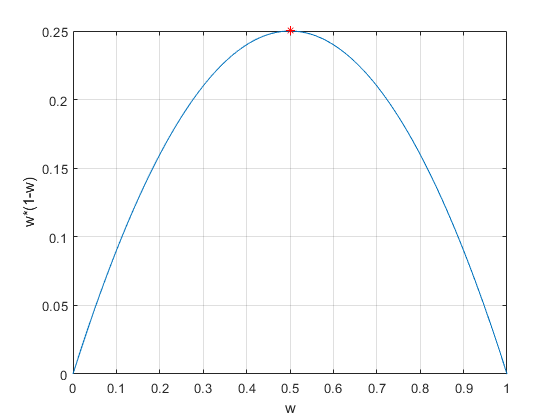

figure(3)
plot(w,y(w))

grid on
hold on


xlabel('w')
ylabel('w*(1-w)')


%okreslenie maksimum
x0=0;

xmax = fminsearch(@(w) -y(w),x0)
plot(xmax,y(xmax),'r*')

## 
$$n_{\min } =\frac{z_{\frac{\alpha }{2}}^2 }{{4d}^2 },0<d<1,$$


gdzie:

d - zakładana dokładność estymacji przedziałowej (połowa długości przedziału ufności),

$z_{\frac{\alpha }{2}}$ - wartość zmiennej losowej o rozkładzie normalnym standaryzowanym pola o mierze $\frac{\alpha }{2}$ (z prawej strony).

Przykład

format long
p=0.9

p =    0.900000000000000


d=0.02

d =    0.020000000000000


alpha=1-p

alpha =    0.100000000000000


pLo = alpha/2;
pUp = 1 - pLo;

z_alpha_2=norminv(pUp)

z_alpha_2 =    1.644853626951472



nmin=z_alpha_2^2 /(4*d^2)

nmin =      1.690964658809633e+03


ceil(nmin)

ans =         1691


Próba powinna zawierać 1691 widzów aby z prawdopodobieństwem 90% oszacować z dokładnością 2% odsetek widzów TV którzy zapamiętają slogan reklamowy.

Gdy zwiększymy prawdopodobięństwo:

Do p= 95%

format long
p=0.95

p =    0.950000000000000


d=0.02

d =    0.020000000000000


alpha=1-p

alpha =    0.050000000000000


pLo = alpha/2;
pUp = 1 - pLo;

z_alpha_2=icdf("Normal",pUp,0,1)

z_alpha_2 =    1.959963984540054



nmin=z_alpha_2^2 /(4*d^2)

nmin =      2.400911762933828e+03


ceil(nmin)

ans =         2401


Próba powinna zawierać 2401 widzów aby z prawdopodobieństwem 95% oszacować z dokładnością 2% odsetek widzów TV którzy zapamiętają slogan reklamowy.

Do p= 99%

p=0.99

p =    0.990000000000000


d=0.02

d =    0.020000000000000


alpha=1-p

alpha =    0.010000000000000


pLo = alpha/2;
pUp = 1 - pLo;

z_alpha_2=icdf("Normal",pUp,0,1)

z_alpha_2 =    2.575829303548900



nmin=z_alpha_2^2 /(4*d^2)

nmin =      4.146810375638258e+03


ceil(nmin)

ans =         4147


Próba powinna zawierać 4147 widzów aby z prawdopodobieństwem 99% oszacować z dokładnością 2% odsetek widzów TV którzy zapamiętają slogan reklamowy.

Do p= 99% i d = 1 %

p=0.99

p =    0.990000000000000


d=0.01

d =    0.010000000000000


alpha=1-p

alpha =    0.010000000000000


pLo = alpha/2;
pUp = 1 - pLo;

z_alpha_2=icdf("Normal",pUp,0,1)

z_alpha_2 =    2.575829303548900



nmin=z_alpha_2^2 /(4*d^2)

nmin =      1.658724150255303e+04


ceil(nmin)

ans =        16588


Próba powinna zawierać 16588 widzów aby z prawdopodobieństwem 99% oszacować z dokładnością 1% odsetek widzów TV którzy zapamiętają slogan reklamowy.